## 1D FEM Sample Model

% Sloution Benchmark
u  = @(x) [sin(x) ;  cos(x)] ;
Du = @(x) [cos(x) ; -sin(x)] ; 

% System Settings
m  = 2 ;  % number of dependent variables
A1 = @(x) [cos(x), -sin(x); sin(x), cos(x)] ;
A0 = @(x) [cos(x), -sin(x); sin(x), cos(x)] ;
f  = @(x) [1 ; 1] ;
g  = @(x) sin(x) + cos(x)    ;
ab = [ 0 , pi ] ;                 % ab = [ a , b ] domain

% Construct the model
model = Collocation1D(m, ab);
model.fitInterior(A1,A0,f,2)
model.fitBoundary([],@(x) [1,1],g,1)
model.fitTrueSol(u, Du)

% Discretization
n = 10; %50 ;                         % n global vertices
model.linear_discretize(n)

% Points Selection
rng(42) ;  % random seed
h = model.gm.Mesh.MinElementSize;
k = 10

k = 10

interior_points = linspace(ab(1), ab(2), k*n) ; % interior points
boundary_points = ab ; % boundary points

% System assemble
Lambda = diag(h.^(-3/2)*ones(1,1)) ;       % square(weights) for BC
[B_Omega, d_Omega, ~] = model.Assemble_B_Omega(interior_points) ;
[B_Gamma, d_Gamma, ~] = model.Assemble_B_Gamma(boundary_points, Lambda) ;
B = [B_Omega ; B_Gamma] ; d = [d_Omega ; d_Gamma];
[mB,nB] = size(B_Omega); mS = 3*nB; num_coworker = 3;

addpath('./Skechers/'); data = cell(1,10);
for i = 1:10
    switch i
        case 1
            continue
        case 2
            SB = sketching(mS, B_Omega, 'Gaussian');
        case 3
            SB = sketching(mS, B_Omega, 'Hashing', {1, 'Regular'});
        case 4
            s = ceil(log(nB));
            SB = sketching(mS, B_Omega, 'Hashing', {s, 'Regular'});
        case 5
            [lev_score, ~, ~] = leverageScore(B_Omega,'Exact','svd');
            p = lev_score./sum(lev_score);
            SB = sketching(mS, B_Omega, 'Levscore', p);
        case 6
            continue
        case 7
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Gaussian');
        case 8
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Hashing', {1, 'Regular'});
        case 9
            s = ceil(log(nB));
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Hashing', {s, 'Regular'});  
        case 10
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Levscore', {'Exact','svd'});
    end
    data{i} = SB;
end

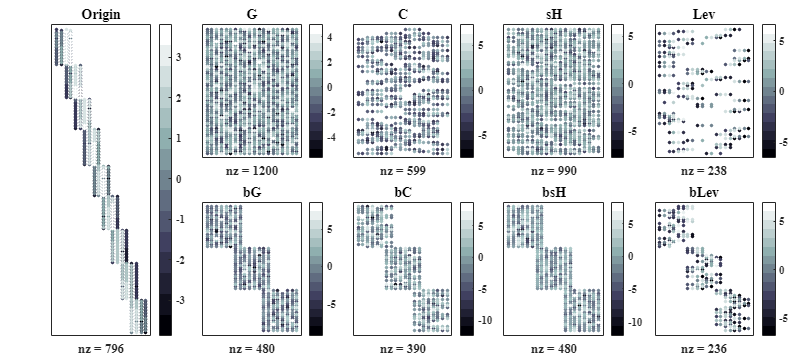

figure; set(gcf,'position',[0, 0, 1000, 450]); t = tiledlayout(2,5); 
errtitles = {'Origin', 'G', 'C', 'sH',  'Lev',...
             [], 'bG', 'bC', 'bsH',  'bLev'};
hY1 = [1,2]; hY2 = [2,2];

for i = 1:10

    if i ~= 1 && i ~= 6
        nexttile(i)
        cspy(data{i},'ColorMap','bone');
        ylim([-hY1(1), size(data{i},1)+hY1(2)]); yticks([]);
    elseif i == 1
        nexttile(1,[2,1])
        cspy(B_Omega,'ColorMap','bone');
        ylim([-hY2(1), size(B_Omega,1)+hY2(2)]); yticks([]);
    else
        continue
    end

    box on
    set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
    title(errtitles{i},'fontweight','bold','FontSize',13);
    xlim([0, size(B_Omega,2)+1]); xticks([]); 
    ax.XAxisLocation = 'bottom';
end

t.TileSpacing = 'compact';
t.Padding = 'compact';

## 1D FEM Sample Model

% Start from here
addpath('./Skechers/');
load('./data/1DsktSample/1DsktSampleModel_small.mat');
B_Omega = model.Omega_assemble.B; d_Omega = model.Omega_assemble.d;
B_Gamma = model.Gamma_assemble.B; d_Gamma = model.Gamma_assemble.d;
B = [B_Omega ; B_Gamma]; d = [d_Omega ; d_Gamma]; 
[mB,nB] = size(B_Omega); mS = 3*nB; num_coworker = 25;

data = cell(1,10);
for i = 1:10
    switch i
        case 1
            continue
        case 2
            SB = sketching(mS, B_Omega, 'Gaussian');
        case 3
            SB = sketching(mS, B_Omega, 'Hashing', {1, 'Regular'});
        case 4
            s = ceil(log(nB));
            SB = sketching(mS, B_Omega, 'Hashing', {s, 'Regular'});
        case 5
            [lev_score, ~, ~] = leverageScore(B_Omega,'Exact','svd');
            p = lev_score./sum(lev_score);
            SB = sketching(mS, B_Omega, 'Levscore', p);
        case 6
            continue
        case 7
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Gaussian');
        case 8
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Hashing', {1, 'Regular'});
        case 9
            s = ceil(log(nB));
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Hashing', {s, 'Regular'});  
        case 10
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Levscore', {'Exact','svd'});
    end
    data{i} = SB; i
end

i = 2

i = 3

i = 4

i = 5

i = 7

i = 8

i = 9

i = 10

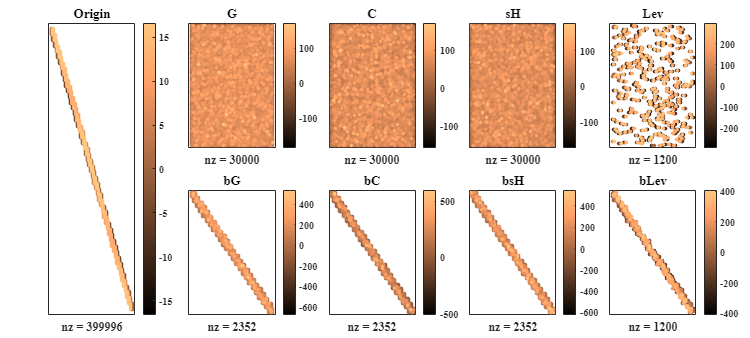

figure; set(gcf,'position',[0, 0, 1000, 450]); t = tiledlayout(2,5); 
errtitles = {'Origin', 'G', 'C', 'sH',  'Lev',...
             [], 'bG', 'bC', 'bsH',  'bLev'};
hY1 = [5,5]; hY2 = [2000,2000];

for i = 1:10

    if i ~= 1 && i ~= 6
        nexttile(i)
        cspy(data{i},'ColorMap','copper');
        ylim([-hY1(1), size(data{i},1)+hY1(2)]); yticks([]);
    elseif i == 1
        nexttile(1,[2,1])
        cspy(B_Omega,'ColorMap','copper');
        ylim([-hY2(1), size(B_Omega,1)+hY2(2)]); yticks([]);
    else
        continue
    end

    box on
    set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
    title(errtitles{i},'fontweight','bold','FontSize',13);
    xlim([-2, size(B_Omega,2)+3]); xticks([]); 
    ax.XAxisLocation = 'bottom';
end

t.TileSpacing = 'compact';
t.Padding = 'compact';

## 2D FEM Sample Model

% Start from here
addpath('./Skechers/');
load('./data/2DsktSample/2DsktSampleModel_small.mat');
B_Omega = model.Omega_assemble.B; d_Omega = model.Omega_assemble.d;
B_Gamma = model.Gamma_assemble.B; d_Gamma = model.Gamma_assemble.d;
B = [B_Omega ; B_Gamma]; d = [d_Omega ; d_Gamma]; 
[mB,nB] = size(B_Omega); mS = 3*nB; num_coworker = 50;

data = cell(1,10);
for i = 1:10
    switch i
        case 1
            continue
        case 2
            SB = sketching(mS, B_Omega, 'Gaussian');
        case 3
            SB = sketching(mS, B_Omega, 'Hashing', {1, 'Regular'});
        case 4
            s = ceil(log(nB));
            SB = sketching(mS, B_Omega, 'Hashing', {s, 'Regular'});
        case 5
            [lev_score, ~, ~] = leverageScore(B_Omega,'Exact','svd');
            p = lev_score./sum(lev_score);
            SB = sketching(mS, B_Omega, 'Levscore', p);
        case 6
            continue
        case 7
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Gaussian');
        case 8
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Hashing', {1, 'Regular'});
        case 9
            s = ceil(log(nB));
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Hashing', {s, 'Regular'});  
        case 10
            SB = blockEmbedding(mS, B_Omega, num_coworker, 'Levscore', {'Exact','svd'});
    end
    data{i} = SB; i
end

i = 2

i = 3

i = 4

i = 5

i = 7

i = 8

i = 9

i = 10

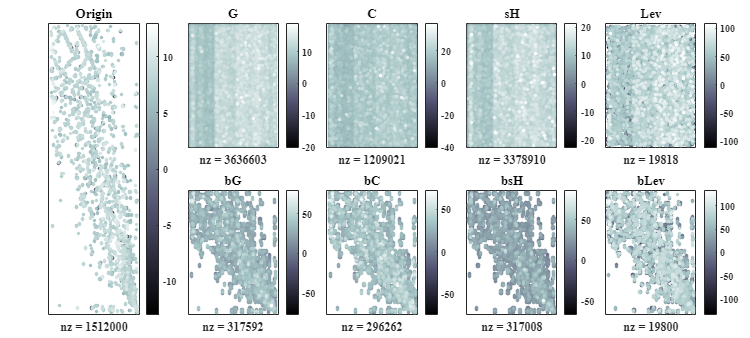

figure; set(gcf,'position',[0, 0, 1000, 450]); t = tiledlayout(2,5); 
errtitles = {'Origin', 'G', 'C', 'sH',  'Lev',...
             [], 'bG', 'bC', 'bsH',  'bLev'};
hY1 = [70,70]; hY2 = [2000,2000];

for i = 1:10

    if i ~= 1 && i ~= 6
        nexttile(i)
        cspy(data{i},'ColorMap','bone');
        ylim([-hY1(1), size(data{i},1)+hY1(2)]); yticks([]);
    elseif i == 1
        nexttile(1,[2,1])
        cspy(B_Omega,'ColorMap','bone');
        ylim([-hY2(1), size(B_Omega,1)+hY2(2)]); yticks([]);
    else
        continue
    end

    box on
    set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
    title(errtitles{i},'fontweight','bold','FontSize',13);
    xlim([-30, size(B_Omega,2)+30]); xticks([]); 
    ax.XAxisLocation = 'bottom';
end

t.TileSpacing = 'compact';
t.Padding = 'compact';